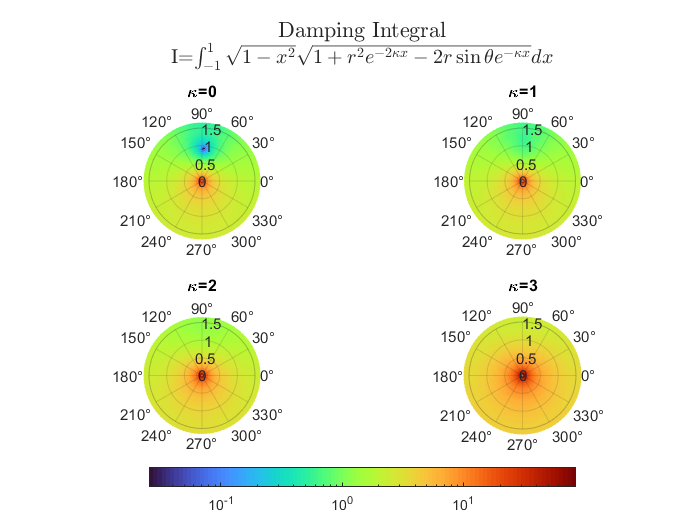

clear
r_primve_vec = linspace(.05,1.5,25);
r_vec = 1./r_primve_vec;
theta_vec = 0:pi/48:2*pi;
kappa_vec = 0:3;
[R,TH,K] = meshgrid(r_vec,theta_vec,kappa_vec);

T = zeros(size(R));

for i=1:numel(R)
    T(i) = integral(@(x)f(x,R(i), TH(i), K(i)), -1, 1);
end

figure
t = tiledlayout(2,2);
for i=1:length(kappa_vec)
    r_prime = 1./R(:,:,i);
    theta = TH(:,:,i);
    x = r_prime .* cos(theta);
    y = r_prime .* sin(theta);
    
    all_val = log(T(:));
    val = log(T(:,:,i));

    val_0_1 = ( val - min(all_val) ) / (max(all_val) - min(all_val)); % continuous 0 to 1
    val_0_100 = round(val_0_1*100); % integer 0 to 100
    colmap = colormap(turbo(101)); % indexed by integer 1 to 101
    color = colmap(val_0_100+1,:);
    sz = r_prime(:)*30;

    nexttile
    polarscatter(theta(:), r_prime(:), sz, color, 'filled');

    colormap(colmap)
    clim(exp([min(all_val), max(all_val)]))
    set(gca,'colorscale','log')

    title( ['\kappa=' num2str(kappa_vec(i))] )
    ax = gca;
    ax.Layer = 'top';
end
cb = colorbar;
cb.Layout.Tile = 'south';
title(t,{'Damping Integral'},{'I=$\int_{-1}^1 \sqrt{1-x^2}\sqrt{1+r^2e^{-2\kappa x}-2r\sin\theta e^{-\kappa x}} dx$'},'Interpreter','latex')

function f = f(x,r,theta,kappa)
    t1 = 1 - r .* sin(theta) .* exp(-kappa .* x);
    t2 =     r .* cos(theta) .* exp(-kappa .* x);
    f = sqrt(1-x.^2) .* sqrt( t1.^2 + t2.^2 );
end